# Blockkurs Tutorial 1: Programmieren in MATLAB

## ToDo

- beschreiben wie ausführen ganz am anfang

- Workspace (zeigen variablen dort gespeichert), Daten, Folder etc., alle Fenster in MATLAB

- Test mit Hiwis

- comments im code erklären mit %

- konkatenieren

%% Pfade setzen

%Pfad zu den Daten
pathToData='C:\Users\mtroen\Dropbox\AA_Teaching\Blockkurs_Auswertung_neurophysiologische_Experimente\FS_2024\Praxis\data';
pathToData='data'

%Pfad zu EEGlab
addpath('eeglab2021.1')

%% EEG daten laden
load( [pathToData  '/sub-002.mat'] );

%load in "EEG". EEG ist einem neuen format von Daten: "struct"

for i=2:4
   allEEG{i}=  load( [pathToData  '/sub-00' num2str(i) '.mat'] );
end

%% Finaler check: Signal processing toolbox installiert?

a = 5

Im Folgenden...

Text normal, Code grau hinterlegt

Exkurse am Ende von Kapiteln nicht nötig, dürfen auch übersprungen werden, nur für interessierte

die idee ist hier nicht, alles auswendig zu lernen, sondern zu verstehen, wie programmierem mit matlab funktioniert

## 1.1 Variablen

**Variablen** sind **Speicherorte**. Sie sind wichtig, da sie es uns ermöglichen, Werte zu speichern und diese später im Code wieder zu verwenden, ohne den Wert jedes Mal erneut eingeben zu müssen. 

In MATLAB können wir eine Variable erstellen, indem wir ihr einen Namen geben und ihr mit dem Zeichen '=' einen Wert zuweisen. 

% Erstellen einer Variable 'a' für eine Zahl
a = 5

b = 3

Wir können also unserer Variable 'a' den Wert 5 zuordnen. Machen wir das nun mit einer zusätzlichen Variable:

% Erstellen einer zusätzlichen Variable 'b' für eine Zahl
b = 3

ans = 8

ans = 2

Jetzt haben wir unserer zweiten Variable 'b' den Wert 3 zugeordnet.

Mit diesen Variablen können wir nun jegliche **mathematischen Operationen** ausführen.

% Mathematische Operationen mit Variablen

ans = 15

a + b    % Addition

ans = 1.6667

a - b    % Subtraktion

ans = 2.2361

a * b    % Multiplikation

ans = 125

a / b    % Division
sqrt(a)  % Wurzel
a^b      % Exponent

add = 8

sub = 2

Auf der rechten Seite werden nun die Resultate der mathematischen Operationen angezeigt. Wie du vielleicht schon bemerkt hast, werden nicht mehr nur die blossen Zahlen ausgegeben, sondern jetzt steht vor jedem Resultat 'ans'. MATLAB gibt uns hier die Antwort (darum 'ans', von answer), jedoch wird diese so nicht gespeichert! Um Resultate zu speichern, weisen wir diese einer neuen Variable zu. 

% Mathematische Operationen mit Variablen, Resultate werden gespeichert

mult = 15

add  = a + b    % Addition

div = 1.6667

sub  = a - b    % Subtraktion

wurz = 2.2361

mult = a * b    % Multiplikation

exp = 125

div  = a / b    % Division
wurz = sqrt(a)  % Wurzel
exp  = a^b      % Exponent

Jetzt haben wir alle Variablen gespeichert! Normalerweise möchten wir jedoch nicht, dass wir alle Resultate direkt ausgespuckt kriegen, das kann bei grösseren Skripten nämlich ziemlich unübersichtlich werden. Deshalb schreiben wir in MATLAB hinter jeder Zeile, deren Output wir nicht sehen möchten, das Zeichen ';'.

% Versteckter Ouput durch ';'
add  = a + b;    % Addition

add = 8

     8



Um uns anzeigen zu lassen, was sich in einer Variable befindet, können wir entweder deren Namen eingeben, oder die Funktion '`disp`' (display) verwenden.

% Ausgabe der Werte der Variablen
add
disp(add)

Auf der rechten Seite dieses Fensters sind die Werte nun ersichtlich, die in den Variablen 'a', 'b' und 'add' gespeichert wurden.

Variablen müssen aber nicht unbedingt Zahlen enthalten. Wir können auch **Buchstaben** in Variablen speichern.

% Erstellen einer Variable für Text
name = 'MATLAB';
alphabet = 'A':'Z';

MATLAB


ABCDEFGHIJKLMNOPQRSTUVWXYZ


Um uns anzeigen zu lassen, was sich in einer Variable befindet, können wir wiederum die Funktion '`disp`' verwenden.

% Ausgabe der Werte der Variablen
disp(name);
disp(alphabet);

zeilenVektor =      1     2     3     4     5


**EXKURS**: Der Name der Variablen kann frei gewählt werden, sollte jedoch aussagekräftig und selbsterklärend sein, um die Lesbarkeit des Codes zu erhöhen. Die Konvention beim Programmieren ist dabei das sogenannte camelCase. Das camelCase beschreibt eine Art der Schreibweise von Variablennamen, bei der mehrere Wörter ohne Trennzeichen aneinandergereiht werden. Dabei werden die Anfangsbuchstaben ab dem zweiten Wort grossgeschrieben, um die Lesbarkeit zu verbessern. Der Name rührt daher, dass die grossen Anfangsbuchstaben wie die Höcker eines Kamels aussehen. Beispiele: variablenNamen, zeilenVektor, spaltenVektor.

## 1.2 Arrays und Matrizen

Ein **Array** ist eine **Sammlung von Werten**, die in einer bestimmten Reihenfolge angeordnet sind. Ein Array wird mit eckigen Klammern `[]` erstellt, wobei die Werte mit Kommas, Strichpunkten oder Leerzeichen getrennt werden.

Ein eindimensionales Array (wie eine Liste) nennen wir in MATLAB **Vektor**. Dabei kann diese eine Dimension entweder eine Zeile sein, oder eine Spalte.

% Erstellen eines Zeilenvektors (Array mit einer Zeile)
zeilenVektor = [1, 2, 3, 4, 5]

spaltenVektor =      6
     7
     8
     9
    10



% Erstellen eines Spaltenvektors (Array mit einer Spalte)
spaltenVektor = [6; 7; 8; 9; 10]

matrix =      1     2     3
     4     5     6


Wie du oben sehen kannst, werden Werte, die in derselben Zeile stehen sollen, mit einem Komma getrennt. Wenn wir die Werte in einer neuen Zeile haben möchten, trennen wir sie mit einem Strichpunkt (';').

Nun kann man Zeilen und Spalten beliebig verbinden. Ein daraus resultierendes zweidimensionales Array (ähnlich einer Tabelle) nennen wir in MATLAB **Matrix**.

% Erstellen einer Matrix (2x3 Matrix mit 2 Zeilen und 3 Spalten)
matrix = [1, 2, 3; 4, 5, 6]

buchstabenVektor = 'ABC'

alphabet = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ'

Natürlich können Vektoren und Matrizen auch mit Buchstaben erstellt werden. Einen Buchstabenvektor haben wir bereits weiter oben gesehen, als wir uns das Alphabet haben ausgeben lassen.

% Erstellen eines Vektors mit Buchstaben
buchstabenVektor = ['A', 'B', 'C']
alphabet

buchstabenMatrix = 2×3 char array
    'ABC'
    'DEF'



% Erstellen einer Matrix mit Buchstaben
buchstabenMatrix = ['A', 'B', 'C'; 'D', 'E', 'F']

## 1.3 Klammern 

**Klammern** haben in MATLAB unterschiedliche Bedeutungen. Runde Klammern `( )` werden oft für die Eingaben von Funktionen und zur Indizierung verwendet. Eckige Klammern `[ ]` werden für das Erstellen von Arrays oder Matrizen verwendet. Geschweifte Klammern `{ }` verwendet man für Zellen-Arrays, die unterschiedliche Datentypen enthalten können.

%runde klammern:
%Elemente aus Arrays/Matrizen abrufen:
array34(5)

%Funktionen auffrufenn
mean(array34)

%Eckige klammern:
%Elemente Verbinden

%erweiterung: geschweifte klammern:
%Für arrays die verschiedenste Daten speichern können.
%Zuvor: z.B. nur Buchstaben, oder nur Zahlen
c_wrong
c_cell={b, x1}

% Rundklammern für die Funktionseingabe
b = sqrt(25);

% Eckige Klammern für das Erstellen eines Arrays
array = [1, 2, 3, 4];

In diesem Beispiel verwenden wir runde Klammern, um der Funktion `sqrt` die Zahl `25` als Eingabe zu geben. Eckige Klammern werden verwendet, um ein Array mit den Werten `1, 2, 3, und 4` zu erstellen.

## 1.4 Indizierung

**Indizierung** nennt man die Methode, mit der man auf bestimmte Elemente eines Arrays oder einer Matrix zugreift. In MATLAB beginnt die Indizierung bei `1`, das heisst, das erste Element eines Arrays hat den Index `1`. Man kann auf Elemente zugreifen, indem man die Position des Elements in runden Klammern angibt.

Bei einem Vektor ist das ganz einfach. Wir geben einfach genau die Position des Elements in der Liste an.

% Zugriff auf ein bestimmtes Element in einem Array
array = [10, 20, 30, 40];
zweitesElement = array(2)

zweitesElement = 20

In einer Matrix funktioniert das genau gleich! Jedoch müssen wir hier angeben, in welcher Zeile und in welcher Spalte sich unser gewünschstes Element befindet. In der Matrix greifen wir mit `matrix(2, 3)` auf das Element in der zweiten Zeile und dritten Spalte zu, was hier `6` ist.

% Zugriff auf ein Element in einer Matrix
matrix = [1, 2, 3; 4, 5, 6];
sechs = matrix(2, 3); % Zweite Zeile, dritte Spalte

**EXKURS**: Natürlich kann man hier auch wieder geschickt eine Funktion verwenden. Beispielweise kann man mit der Funktion `find` den Index eines bestimmten Wertes finden.

% Index finden im Array
vierzigArrayIndex = find(array == 40)

vierzigArrayIndex = 4

array(vierzigArrayIndex)

ans = 40


% Index finden in einer Matrix
[fuenfZeileMatrixIndex, fuenfSpalteMatrixIndex] = find(matrix == 5)

fuenfZeileMatrixIndex = 2

fuenfSpalteMatrixIndex = 2

matrix(fuenfZeileMatrixIndex, fuenfSpalteMatrixIndex)

ans = 5

Im Exkurs wird gezeigt, wie man mit der Funktion `find` die Position (Index) eines bestimmten Wertes in einem Array oder einer Matrix findet und dann auf dieses Element zugreift: Mit `find(array == 40)` wird der Index des Wertes `40` im Array gefunden. Dieser Index (hier: vierte Stelle im array) wird genutzt, um direkt auf das Element zuzugreifen: `array(vierzigArrayIndex)`. Mit `[fuenfZeileMatrixIndex, fuenfSpalteMatrixIndex] = find(matrix == 5)` werden die Zeilen- und Spaltenindizes des Wertes `5 (2, 2)` in der Matrix gefunden. Anschließend kann direkt auf das Element zugegriffen werden: `matrix(fuenfZeileMatrixIndex, fuenfSpalteMatrixIndex)`. Die Funktion `find` gibt also die Position(en) zurück, an denen die Bedingung erfüllt ist. Diese können direkt für den Zugriff auf das Element verwendet werden.

## 1.5 Funktionen

**Funktionen** sind spezielle Befehle aus vorprogrammiertem Code, die eine bestimmte Aufgabe ausführen.

Wir kennen bereits zwei Funktionen! Im Kapitel 1.1 Variablen haben wir 'disp' und 'sqrt' kennengelernt. Funktionen werden durch ihren Namen aufgerufen und nehmen Argumente (Eingaben) in runden Klammern `( )` entgegen. Sie geben ein Ergebnis zurück, das in einer Variable gespeichert werden kann.

% Berechnung der Quadratwurzel einer Zahl
wurzel = sqrt(16);

% Ausgabe des Ergebnisses
disp(wurzel)

     4



Hier wird die Funktion '`sqrt`' verwendet, um die Quadratwurzel der Zahl `16` zu berechnen. Das Ergebnis, `4`, wird in der Variable `wurzel` gespeichert. Dieses Ergebnis geben wir mit der Funktion '`disp`' aus.

In MATLAB gibt es viele eingebaute Funktionen, die häufige mathematische Berechnungen durchführen. Beispielsweise können wir uns den Mittelwert ausgeben lassen. Wir zeigen das nun direkt anhand unser gerade eben definierten Vektoren.

% Berechnung des Mittelwerts aus einem Vektor
mittelwertZeilenVektor = mean(zeilenVektor)

mittelwertZeilenVektor = 3

Der Mittelwert aus unserer Variable `zeilenVektor` ist also 3. Das Ganze geht natürlich genau gleich mit der Variable `spaltenVektor`.

% Berechnung des Mittelwerts aus einem Vektor
mittelwertSpaltenVektor = mean(spaltenVektor)

mittelwertSpaltenVektor = 8

Bei `spaltenVektor` ist der Mittelwert also 8. Funktionen erleichtern uns komplexe Berechnungen, da wir nur den Namen der Funktion und die Eingabewerte angeben müssen. 

Es gibt zahlreiche andere Funktionen, die in MATLAB verwendet werden können. Wir werden noch viele andere Funktionen im Kurs kennenlernen. Zwei essenzielle Funktionen, die ständig verwendet werden, lernen wir hier kennen.

In MATLAB können wir nur bestimmte Teile des Codes ausführen, indem wir **Bedingungen** verwenden. Eine Bedingung ist wie eine Frage, die entweder mit *wahr* (true) oder *falsch* (false) beantwortet wird. Je nachdem, ob die Bedingung wahr oder falsch ist, wird ein bestimmter Teil des Codes ausgeführt. Dafür verwenden wir die **if-else-Struktur**.

% Beispiel: Überprüfung, ob eine Zahl positiv ist
zahl = -5;
if zahl > 0
    disp('Die Zahl ist positiv.');
else
    disp('Die Zahl ist negativ.');
end

Die Zahl ist negativ.


Hier überprüfen wir, ob die Variable `zahl` grösser als 0 ist. Wenn ja, wird `'Die Zahl ist positiv.'` ausgegeben. Wenn die Variable `zahl` kleiner als 0 ist, wird `'Die Zahl ist negativ.'` ausgegeben. Anstatt > und < kann man auch == (gleich) und ~= (ungleich) verwenden. Die if-else-Struktur muss immer mit einem abschliessenden `end` geschlossen werden.

**1.5.2 For-Schleifen**

For-Schleifen werden verwendet, um eine bestimmte Aktion wiederholt auszuführen. Die Anzahl der Wiederholungen wird durch die Schleifenvariable definiert.

% Beispiel: Zahlen von 1 bis 5 ausgeben

for i = 1:5

disp(['Die aktuelle Zahl ist: ', num2str(i)]);

end

In diesem Beispiel:

- Definieren wir `i` als Schleifenvariable, die von 1 bis 5 läuft.

- Bei jedem Durchlauf wird die aktuelle Zahl mit `disp` ausgegeben.

% Loop, die die zahlen 1 bis 10 auf dem Command Window ausgibt
meineVar=1;
for i=1:1:10
    %Aktueller Schleifendurchlauf XX, aktueller wert von i:YY 
    disp(['Aktueller wert von i: ' num2str(i) ', aktueller Wert von zaehler: ' num2str(meineVar)]) 
    %variable zaehler so manipulieren dass in jedem durchlauf der wert um 1
    %erhöht wird
    meineVar=meineVar*2;
end

% 2 if statements, which give different console output depending on the
% current value of i

**Hinweis:**

- Die Schleifenvariable wird automatisch aktualisiert.

- `num2str` wandelt Zahlen in Text um, damit wir sie in einer Textnachricht verwenden können.

% Beispiel: Quadrate der Zahlen von 1 bis 5 berechnen und speichern
quadrate = []; % Leeres Array zum Speichern der Ergebnisse
for i = 1:5
    quadrate(i) = i^2;
end

Die Quadrate der Zahlen von 1 bis 5:


disp('Die Quadrate der Zahlen von 1 bis 5:');

     1     4     9    16    25



disp(quadrate);

Hier berechnen wir:

- Das Quadrat jeder Zahl von 1 bis 5 und speichern es im Array `quadrate`.

- Am Ende geben wir alle Quadrate auf einmal aus.

## 1.6 Plotten

Plotten bedeutet, Daten grafisch darzustellen. MATLAB bietet dafür viele Funktionen, wobei `plot` am gebräuchlichsten ist. Mit `plot` kann man Werte als Punkte in einem Diagramm darstellen, wobei die x-Werte (horizontale Achse) und die y-Werte (vertikale Achse) angegeben werden.

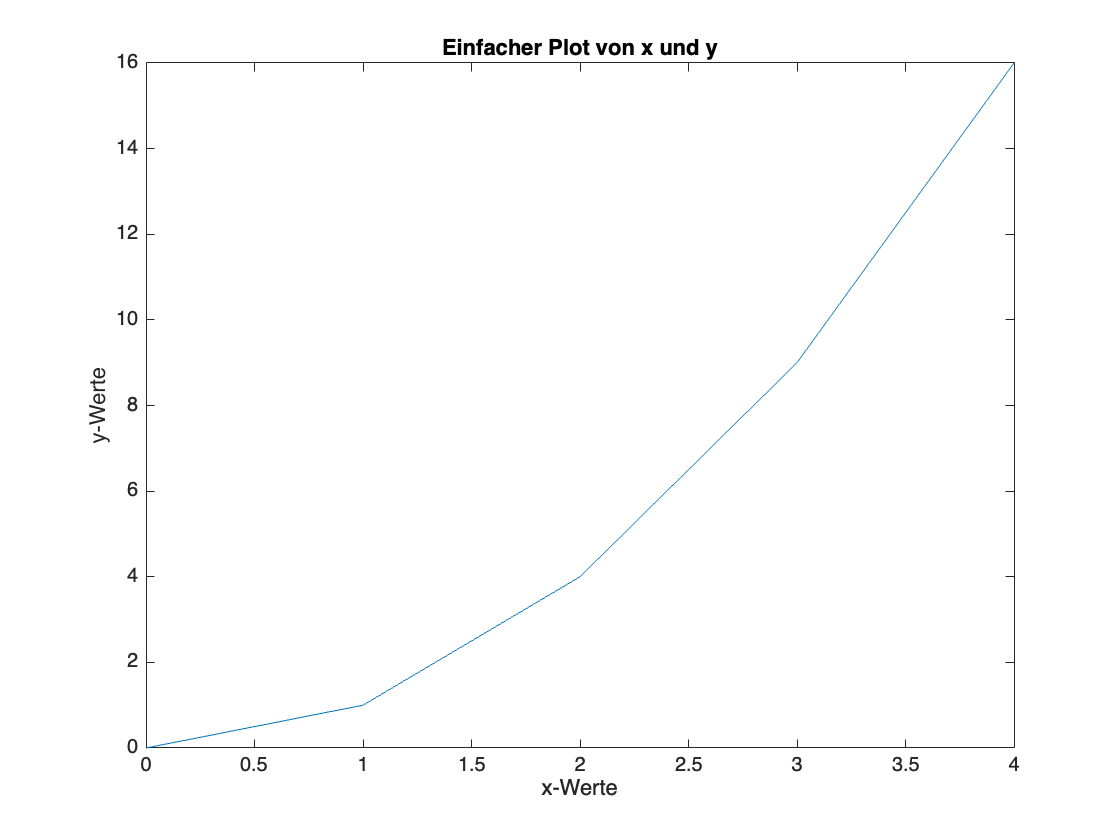

% Erstellen von x- und y-Werten
x = [0, 1, 2, 3, 4];
y = [0, 1, 4, 9, 16];

% Zeichnen des Plots
plot(x, y);

% Hinzufügen von Titeln und Achsenbeschriftungen
title('Einfacher Plot von x und y');

xlabel('x-Werte');
ylabel('y-Werte');

Hier erstellen wir einen Plot, indem wir die Werte von `x` und `y` grafisch darstellen. Jeder Wert in `x` wird mit dem entsprechenden Wert in `y` kombiniert und auf der Karte gezeichnet. Die Achsen können beschriftet werden, um die Daten verständlicher zu machen.